clear; clc;

%scores_fdv=importdata("scores_fdv.mat");
%scores_fdv=scores_fdv(:,2);
scores_fts=importdata("scores_fts.mat");
scores_fts=scores_fts(:,2);
scores_opt=importdata("scores_opt.mat");

num = length(scores_opt); %number of trials
wins = zeros(num,2);
wins(:,1) = scores_fts < scores_opt;
wins(:,2) = scores_opt < scores_fts;
ties = scores_opt == scores_fts;

fts = sum(wins(:,1))

fts = 36924

opt = sum(wins(:,2))

opt = 56482

draw = sum(ties)

draw = 6594

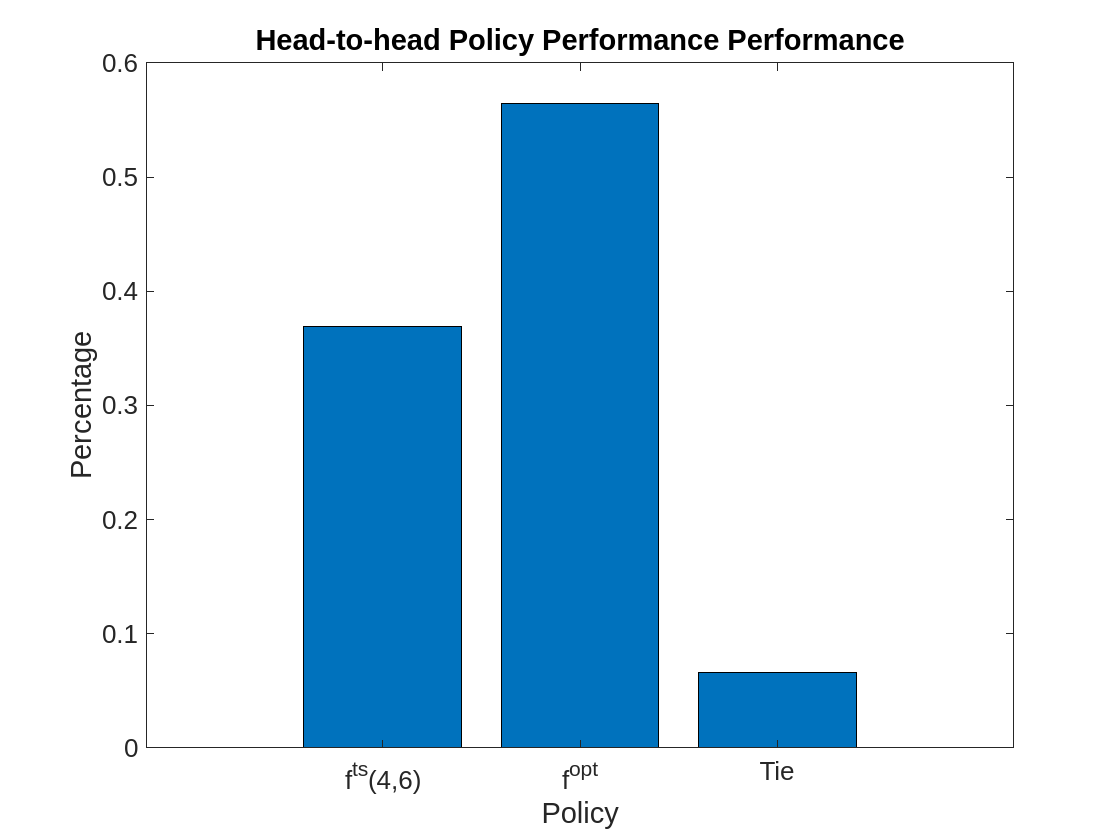

outcome=[fts,opt,draw]/num;
bar(outcome)
ylabel('Percentage')
xlabel('Policy')
set(gca,'xticklabel',{'f^{ts}(4,6)','f^{opt}','Tie'})
title('Head-to-head Policy Performance Performance')
set(gca,'fontsize', 20)